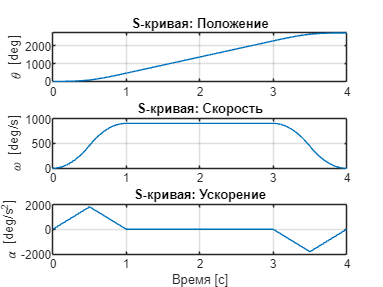

% Параметры задачи
T_total = 4;           % общее время [с]
Theta_total = 2720;    % угол поворота [град]

% Допустим, разгон и торможение по 1с каждый
T_acc = 1;             
T_dec = 1;
T_const = T_total - T_acc - T_dec;

% Вычисляем максимальную скорость
% Участок разгона - трапеция, площадь равна:
% S_acc = (1/2)*V_max*T_acc
% S_dec = (1/2)*V_max*T_dec
% S_const = V_max * T_const
% Итого: Theta_total = S_acc + S_const + S_dec

% Решаем:
% Theta_total = (1/2)*V_max*T_acc + V_max*T_const + (1/2)*V_max*T_dec

V_max = Theta_total / ( (1/2)*T_acc + T_const + (1/2)*T_dec );

% Для S-кривой нужен jerk-профиль
% Для простоты: jerk положителен 0 -> A_max, потом jerk отрицателен A_max -> 0

% Время jerk-участка: пусть всё ускорение за Tj
Tj = T_acc / 2;  % jerk-полуволна

% A_max = V_max / (T_acc - Tj)
A_max = V_max / (T_acc - Tj);

% jerk
J_max = A_max / Tj;

% Формируем временной массив
dt = 0.01;
t = 0:dt:T_total;

% Инициализация
theta = zeros(size(t));
omega = zeros(size(t));
alpha = zeros(size(t));

for i = 2:length(t)
    ti = t(i);

    if ti <= Tj
        % jerk положителен
        J = J_max;
    elseif ti <= T_acc
        % jerk отрицателен
        J = -J_max;
    elseif ti <= T_acc + T_const
        % постоянная скорость
        J = 0;
    elseif ti <= T_acc + T_const + Tj
        % торможение jerk отрицателен
        J = -J_max;
    elseif ti <= T_total
        % торможение jerk положителен
        J = J_max;
    else
        J = 0;
    end

    % интегрируем jerk -> ускорение -> скорость -> путь
    alpha(i) = alpha(i-1) + J*dt;
    omega(i) = omega(i-1) + alpha(i)*dt;
    theta(i) = theta(i-1) + omega(i)*dt;
end

% Графики
figure;
subplot(3,1,1);
plot(t, theta); grid on;
ylabel('\theta [deg]');
title('S-кривая: Положение');

subplot(3,1,2);
plot(t, omega); grid on;
ylabel('\omega [deg/s]');
title('S-кривая: Скорость');

subplot(3,1,3);
plot(t, alpha); grid on;
ylabel('\alpha [deg/s^2]');
xlabel('Время [с]');
title('S-кривая: Ускорение');

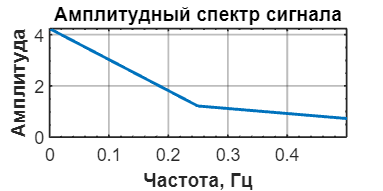

% Преобразование Фурье
Fs = 1/dt;
N = length(t);
f = (0:N-1)*(Fs/N);

fftAll = fft(omega/160);
amp = abs(fftAll)/N;


f_plot = f(1:floor(N/2));
amp_plot = amp(1:floor(N/2)); % <-- правильно
figure('Color','w', 'Position',[100 100 800 400]);  % белый фон и размер

plot(f_plot, amp_plot, 'LineWidth', 2);             % более жирная линия
xlim([0 0.5]);                                       % ограничение по частоте

grid on;

% Подписи осей
xlabel('Частота, Гц', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Амплитуда', 'FontSize', 12, 'FontWeight', 'bold');

% Заголовок
title('Амплитудный спектр сигнала', 'FontSize', 14);
% Стилизация осей
set(gca, ...
    'FontSize', 12, ...
    'LineWidth', 1.2, ...
    'Box', 'on', ...
    'GridAlpha', 0.3, ...
    'XMinorTick', 'on', ...
    'YMinorTick', 'on');